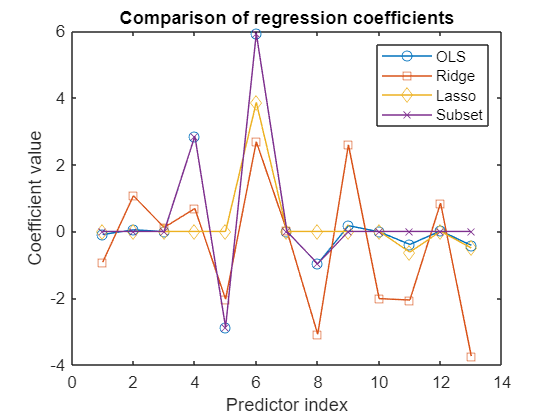

% Load the Boston housing dataset
data = load(['C:\Users\param\OneDrive - Clemson University' ...
    '\Desktop\CU\Fall23\Advance Machine Learning\HW1/housing.data']);

% Extract features and target variable
x = data(:, 1:13);
y = data(:,14);

% Vanilla OLS
x_ols = x\y; % Using the backslash operator for least squares

% Ridge regression
lambda_ridge = 1; % Example regularization parameter for Ridge
x_ridge = ridge(y, x, lambda_ridge);

% Lasso
lambda_lasso = 1; % Example regularization parameter for Lasso
[x_lasso, fitinfo] = lasso(x, y, 'Lambda', lambda_lasso);

% Subset (Simple implementation using a thresholding on OLS coefficients)
threshold = 0.5; % Example threshold
x_subset = x_ols;
x_subset(abs(x_ols) < threshold) = 0;

% Plot
figure;
plot(1:13, x_ols, 'o-', 'DisplayName', 'OLS');
hold on;
plot(1:13, x_ridge, 's-', 'DisplayName', 'Ridge');
plot(1:13, x_lasso, 'd-', 'DisplayName', 'Lasso');
plot(1:13, x_subset, 'x-', 'DisplayName', 'Subset');
xlabel('Predictor index');
ylabel('Coefficient value');
legend();
title('Comparison of regression coefficients');
hold off;